%% Script file: Online Training (Hebbian Learning)
% Example 1: T, G and F.
%% Load the Data and Graph the Results.
T1=[1 1 1 -1;-1 1 -1 -1;-1 1 -1 -1;-1 1 -1 -1];
T2=[-1 1 1 1;-1 -1 1 -1;-1 -1 1 -1;-1 -1 1 -1];
G1=[1 1 1 -1;1 -1 -1 -1; 1 1 1 -1 ; 1 1 1 -1];
G2=[-1 1 1 1;-1 1 -1 -1; -1 1 1 1; -1 1 1 1];
F1=[1 1 1 -1;1 1 -1 -1;1 -1 -1 -1;1 -1 -1 -1];
F2=[-1 1 1 1;-1 1 1 -1;-1 1 -1 -1;-1 1 -1 -1];

gg=colormap(gray); gg=gg(end:-1:1,:);
subplot(2,3,1); imagesc(T1); colormap(gg)
subplot(2,3,2); imagesc(G1);
subplot(2,3,3); imagesc(F1);
subplot(2,3,4); imagesc(T2);
subplot(2,3,5); imagesc(G2);
subplot(2,3,6); imagesc(F2);

%% Main code start
X=[T1(:) T2(:) G1(:) G2(:) F1(:) F2(:)]; %X is 16 x 6
T=[60 60 0 0 -60 -60];
alpha=0.03; %% learning rate 
NumPoints=6; %Number of training points
NumEpochs=60; %An epoch is one pass through the data.
[W,b,EpochErr]=WidHoff(X,T,alpha,NumEpochs);
%% Output results
W*X+b*ones(1,NumPoints)

ans =    60.0000   60.0000   -0.0000   -0.0000  -60.0000  -60.0000


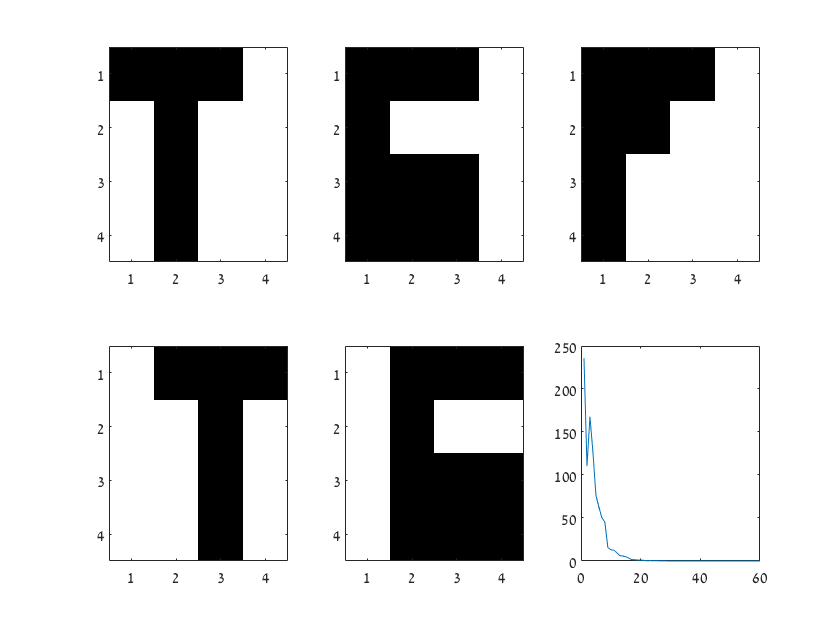

figure(2)
plot(EpochErr);